# **demo07 of writeMesh**

**Tetrahedral mesh**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 350; height = 350;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Load mesh

Let's load the mesh data from "mesh_data_4.mat"

load("mesh_data_4.mat")

We will see 3 variables: vert, ele, tnum

vert

vert =     0.5000    0.5000         0
    0.5000    3.5000         0
    2.5000    0.5000         0
    2.5000    3.5000         0
    5.5000    0.5000         0
    5.5000    3.5000         0
    8.5000    0.5000         0
    8.5000    3.5000         0
    0.5000    0.5000    3.0000
    0.5000    3.5000    3.0000


ele

ele =    628   208    59   246
   665   671   285   178
   683   637   645   657
   679   626   212   620
   705   676   672   691
   664   196   615   657
   700   643   652   701
   643   700   652   653
   679   247   249    61
   684   628   206   635


tnum

tnum =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ele has 4 columns, so it's a linear tetrahedral mesh.

Check the number of phase in the mesh

length(unique(tnum))

ans = 3

## Plot mesh

Use function plotMeshes3d to plot 3d mesh.

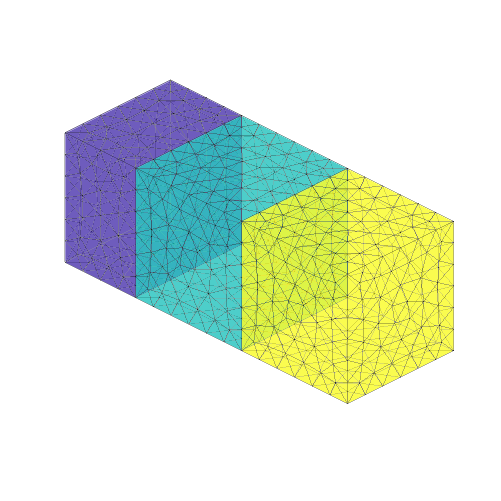

color_code = 2;
opt = [];
opt.faceAlpha = 0.5;
opt.edgeAlpha = 0.3;

plotMeshes3d( vert, ele, tnum, color_code, opt );

We saw 3 phases in the mesh.

## Linear elements

### Display boundary node set

By default, function printInp3d will automatically search and export node sets at the boundary and at the interface of 3d mesh. Before running function printInp3d, we can use function displayBCNode3d to check whether those boundary nodes have been found correctly. Please refer to demo09 for more information.

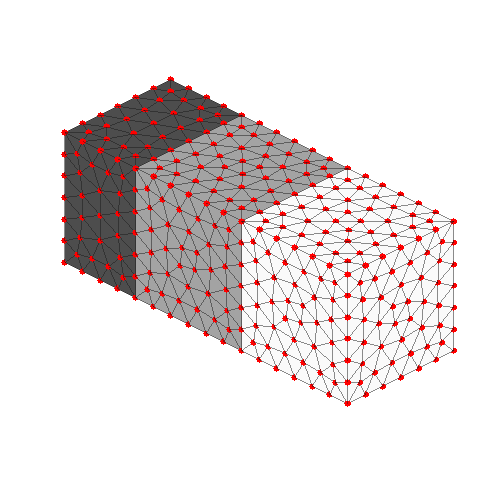

tolerance = 1E-10;
markerSize = 10;
plane = 'all';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

### Export as inp file (Abaqus)

We use function printInp3d to write 3d mesh to inp file. Please refer to demo06 to learn about format setting of inp file.

When using function printInp3d, we can specify element type, precision and file name.

ele_type = 'C3D4';
precision = 8;
file_name = 'test_linear.inp';

printInp3d( vert, ele, tnum, ele_type, precision, file_name );

printInp3d Done! Check the inp file!


### Export as bdf file (Nastran bulk data)

We use function printBdf3d to write 3d mesh to bdf file.

precision = 8;
file_name = 'test.bdf';

printBdf3d( vert, ele, tnum, [], precision, file_name );

printBdf3d Done! Check the bdf file!


## Quadratic elements

### Convert linear elements to quadratic elements

We use function insertNode3d to convert the linear 3d elements to quadratic 3d elements. Function insertNode3d works for tetrahedral and hexahedral mesh.

% vert2, ele2 define quadratic elements
[vert2, ele2] = insertNode3d(vert, ele);

### Display boundary node set

Before running function printInp3d, we can use function displayBCNode3d to check whether those boundary nodes have been found correctly. Please refer to demo09 for more information.

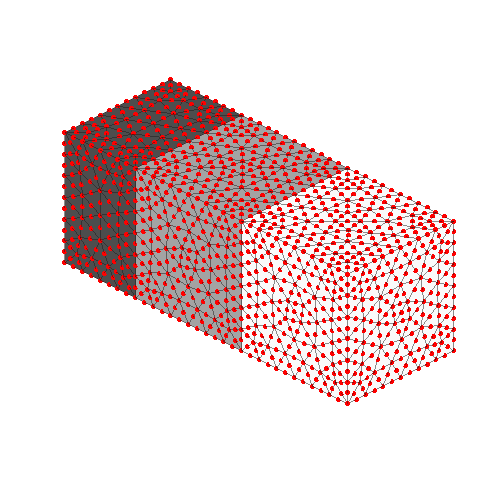

tolerance = 1E-10;
markerSize = 8;
plane = 'all';
displayBCNode3d( vert2, ele2, tnum, tolerance, markerSize, plane );

### Export as inp file (Abaqus)

We use function printInp3d to write 3d mesh to inp file. 

ele_type = 'C3D10';
precision = 8;
file_name = 'test_quadratic.inp';

printInp3d( vert2, ele2, tnum, ele_type, precision, file_name );

printInp3d Done! Check the inp file!


% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo